# LABORATORIO 4 - CINEMÁTICA DIRECTA

## MÓDELO CINEMÁTICO DIRECTO - PHANTOM X

clear
close all
clc
syms theta1 theta2 theta3 theta4
l = [0, 10.49, 10.78, 7.46];
offset = [0, pi/2, 0, 0];
DH = [theta1 5.4 l(1) pi/2 offset(1);
      theta2 0   l(2) 0    offset(2);
      theta3 0   l(3) 0    offset(3);
      theta4 0   l(4) pi/2 offset(4)];


alpha2 = 1.2462

MTH=eye(4);
for i=1:length(DH(:,1))
    row=DH(i,:);
    temp=[cos(row(1)+row(5)), -sin(row(1)+row(5))*cos(row(4)), sin(row(1)+row(5))*sin(row(4)) , row(3)*cos(row(1)+row(5));
          sin(row(1)+row(5)), cos(row(1)+row(5))*cos(row(4)) , -cos(row(1)+row(5))*sin(row(4)), row(3)*sin(row(1)+row(5));
          0          , sin(row(4))             , cos(row(4))                                  , row(2)                   ;
          0          , 0                       , 0                                            , 1                        ];
    MTH=MTH*temp;
end
MTH=simplify(MTH)

$$MTH = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}-\sigma_{2} & \sin\left(\theta_{1}\right) & \sigma_{4}+\sigma_{3} & -\frac{\cos\left(\theta_{1}\right)\,\sigma_{6}}{100}\\ \sigma_{4}-\sigma_{3} & -\cos\left(\theta_{1}\right) & \sigma_{2}-\sigma_{1} & -\frac{\sin\left(\theta_{1}\right)\,\sigma_{6}}{100}\\ \sigma_{5} & 0 & \sigma_{7} & \frac{373\,\sigma_{5}}{50}+\frac{539\,\cos\left(\theta_{2}+\theta_{3}\right)}{50}+\frac{1049\,\cos\left(\theta_{2}\right)}{100}+\frac{27}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{2}=\frac{\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{3}=\frac{\cos\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{4}=\frac{\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{5}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{6}=746\,\sigma_{7}+1078\,\sin\left(\theta_{2}+\theta_{3}\right)+1049\,\sin\left(\theta_{2}\right)\\ \sigma_{7}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

### Gráfica del modelo con el Toolbox de PeterCorke:

q =      0     0     0     0


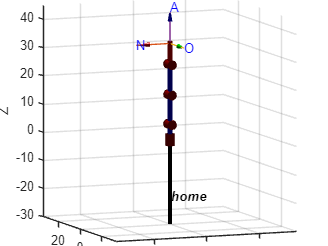

q =    -0.3491    0.3491   -0.3491    0.3491


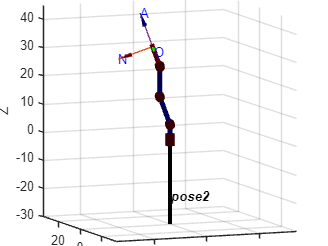

q =     0.5236   -0.5236    0.5236   -0.5236


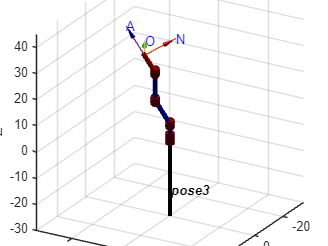

q =    -1.5708    0.2618   -0.9599    0.2967


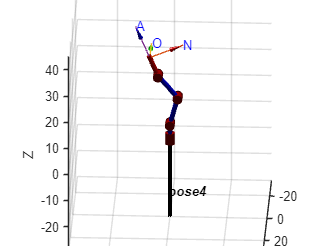

q =    -1.5708    0.7854   -0.9599    0.7854


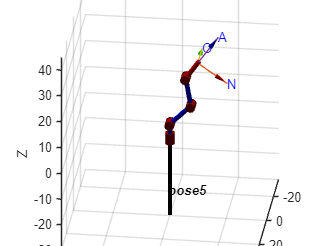

clear
close all
clc
l = [0, 10.49, 10.78, 7.46];
offset = [0, pi/2, 0, 0];

q1 = [0, 0, 0, 0];
q2 = [-20, 20, -20, 20];
q3 = [30,-30, 30, -30];
q4 = [-90, 15, -55, 17];
q5 = [-90, 45, -55, 45];
poses = [q1; q2; q3; q4; q5];

names = ["home", "pose2", "pose3", "pose4", "pose5", "pose6"];

for i = 1:length(poses)

    q = poses(i, :)*pi/180

    % Orden parametros funcion link [THETA D A ALPHA SIGMA(0R,1P) OFFSET]
    DHparameters = [q(1) 5.4 l(1) pi/2 0 offset(1);
                    q(2) 0   l(2) 0    0 offset(2);
                    q(3) 0   l(3) 0    0 offset(3);
                    q(4) 0   l(4) pi/2 0 offset(4)];
    L(1) = Link(DHparameters(1,:));
    L(2) = Link(DHparameters(2,:));
    L(3) = Link(DHparameters(3,:));
    L(4) = Link(DHparameters(4,:)); 
    robot_phantomX = SerialLink(L,'tool',troty(pi/2));
    robot_phantomX.name = names(i);
    figure()
    robot_phantomX.plot(q,'noa');
end